# Unit Testing

The goal is to test the graphical App of the Parking Meter system.

## 1. Clean Session

Clear all remaining variables, figures and timers:

clear variables; close all; clc;
try
  stop(timerfind);
  delete(timerfind);
catch
  disp('No timers are running.');
end

No timers are running.


Add needed classes to the import list:

import matlab.unittest.TestRunner;
import matlab.unittest.TestSuite;
import matlab.unittest.plugins.TestReportPlugin;
import matlab.unittest.plugins.CodeCoveragePlugin;

## 2. Test Runner and Test Suite

Build test runner and test suite allowing to customize how the suite is run and which tests to run.

runner = TestRunner.withTextOutput;

Test report format:

reportName = 'Report';
reportType = 'docx';
switch (reportType)
  case 'docx'
    reportPlugin = TestReportPlugin.producingDOCX([reportName '.' reportType],...
                                                  'IncludingPassingDiagnostics',true,...
                                                  'IncludingCommandWindowText',true);
  case 'html'
    reportPlugin = TestReportPlugin.producingHTML([reportName '.' reportType],...
                                                  'IncludingPassingDiagnostics',true,...
                                                  'IncludingCommandWindowText',true);
  case 'pdf'
    reportPlugin = TestReportPlugin.producingPDF([reportName '.' reportType],...
                                                 'IncludingPassingDiagnostics',true,...
                                                 'IncludingCommandWindowText',true);
  otherwise
    error('Unsupported file type for a report.');
end
runner.addPlugin(reportPlugin);

Coverage report:

coveragePlugin = CodeCoveragePlugin.forFile('..\Component\ParkingMeterGUI.mlapp');
runner.addPlugin(coveragePlugin);

Create the test suite from the defined test class

classSuite = TestSuite.fromClass(?TestApp);

## 3. Initialization

Preparing the parking meter system for the tests:

global UNIT_TESTING;
% Set to true if the MATLAB unit testing API is used, otherwise always false
UNIT_TESTING = true;
% Close any potential running instance of the low-level application
if (system('taskkill /F /im ParkingMeterProject.exe /im cmd.exe &') ~= 0)
  fprintf('No running instance of the low-level application has been detected.\n');
end

No running instance of the low-level application has been detected.


% Call the low-level MATLAB code of the application in a separate process
fprintf('Starting the low-level application instance...\n');

Starting the low-level application instance...


system('..\\Component\\UnitTesting\\ParkingMeterProject.exe&');

## 4. Run Tests

Running TestApp


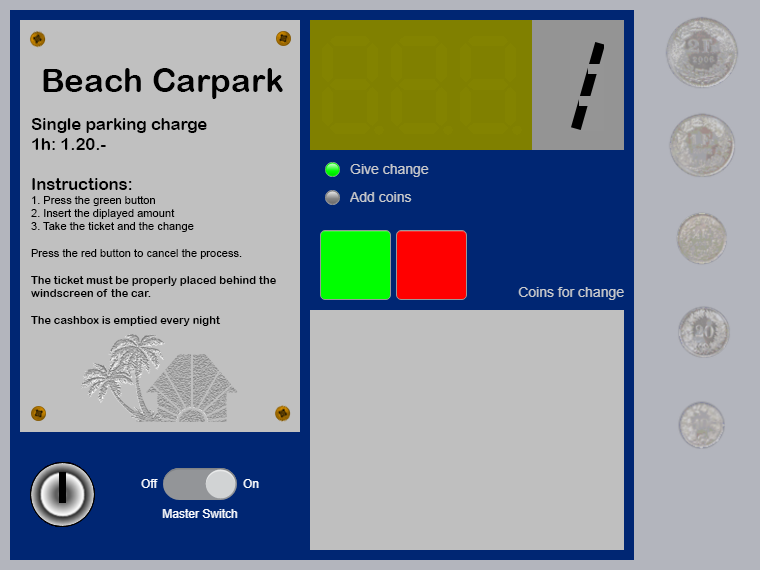

. Processing the test case #1...


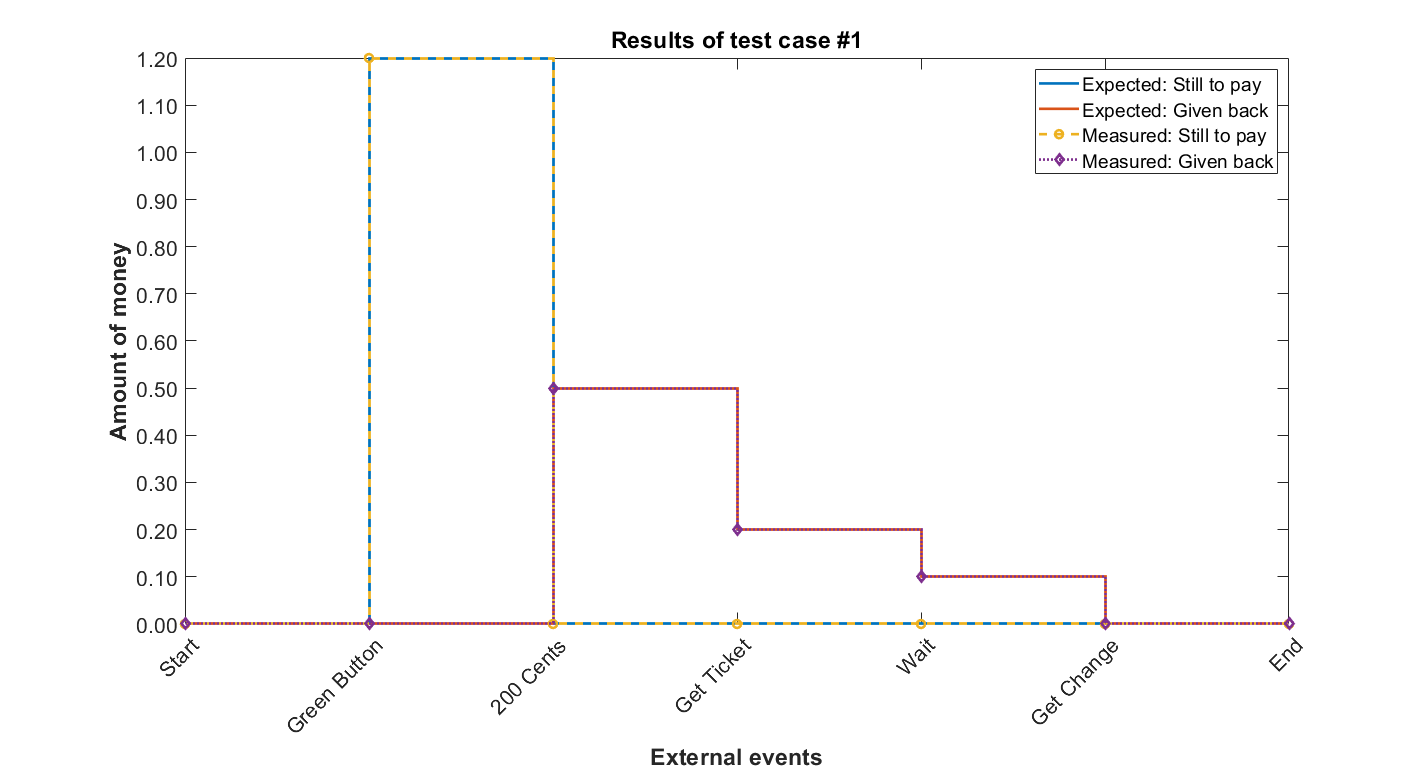


[Terse] Diagnostic logged (2021-02-04 20:24:58):
Figure saved to:
--> C:\Users\sebas\AppData\Local\Temp\f01bf09c-8367-49fb-94e4-bc85156d4bf1\Figure_a74bde4b-f179-4d35-a46e-04175ad4d6e6.fig
--> C:\Users\sebas\AppData\Local\Temp\f01bf09c-8367-49fb-94e4-bc85156d4bf1\Figure_a74bde4b-f179-4d35-a46e-04175ad4d6e6.png
.

 Processing the test case #2...


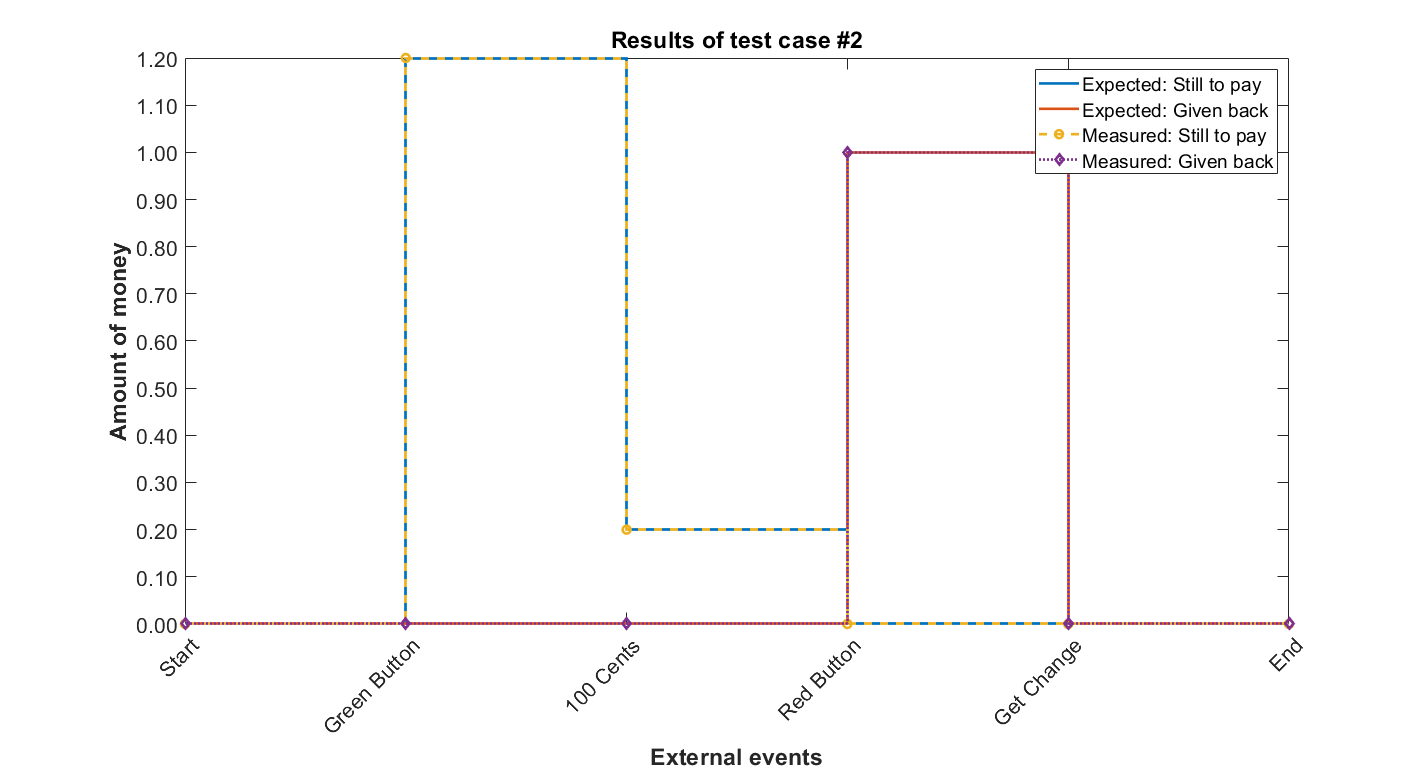


[Terse] Diagnostic logged (2021-02-04 20:25:22):
Figure saved to:
--> C:\Users\sebas\AppData\Local\Temp\f01bf09c-8367-49fb-94e4-bc85156d4bf1\Figure_04af8857-78e7-47f4-9966-1ec69a8c4840.fig
--> C:\Users\sebas\AppData\Local\Temp\f01bf09c-8367-49fb-94e4-bc85156d4bf1\Figure_04af8857-78e7-47f4-9966-1ec69a8c4840.png
.

 Processing the test case #3...


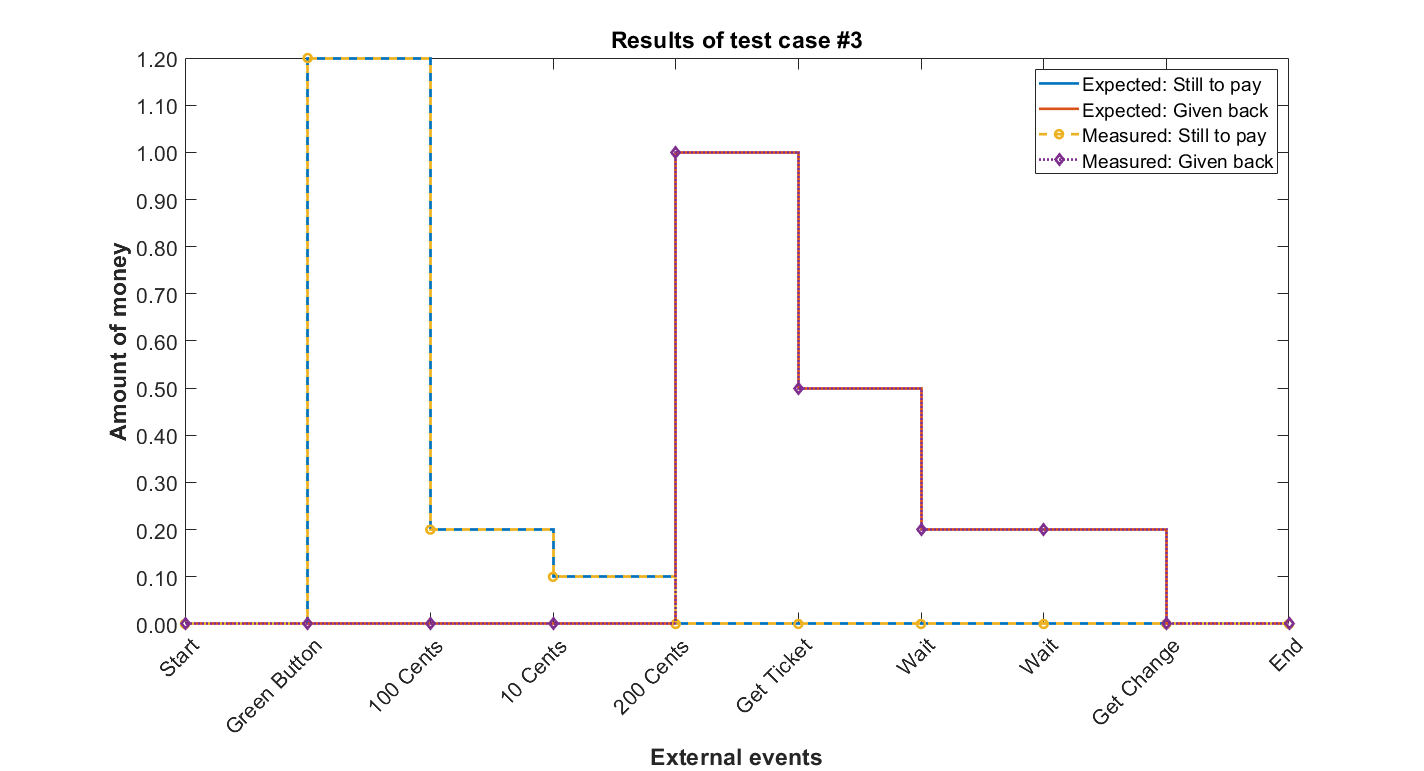


[Terse] Diagnostic logged (2021-02-04 20:25:52):
Figure saved to:
--> C:\Users\sebas\AppData\Local\Temp\f01bf09c-8367-49fb-94e4-bc85156d4bf1\Figure_8e472557-7eff-4e0f-9dc5-aabe10c9ce45.fig
--> C:\Users\sebas\AppData\Local\Temp\f01bf09c-8367-49fb-94e4-bc85156d4bf1\Figure_8e472557-7eff-4e0f-9dc5-aabe10c9ce45.png
.

 Processing the test case #4...


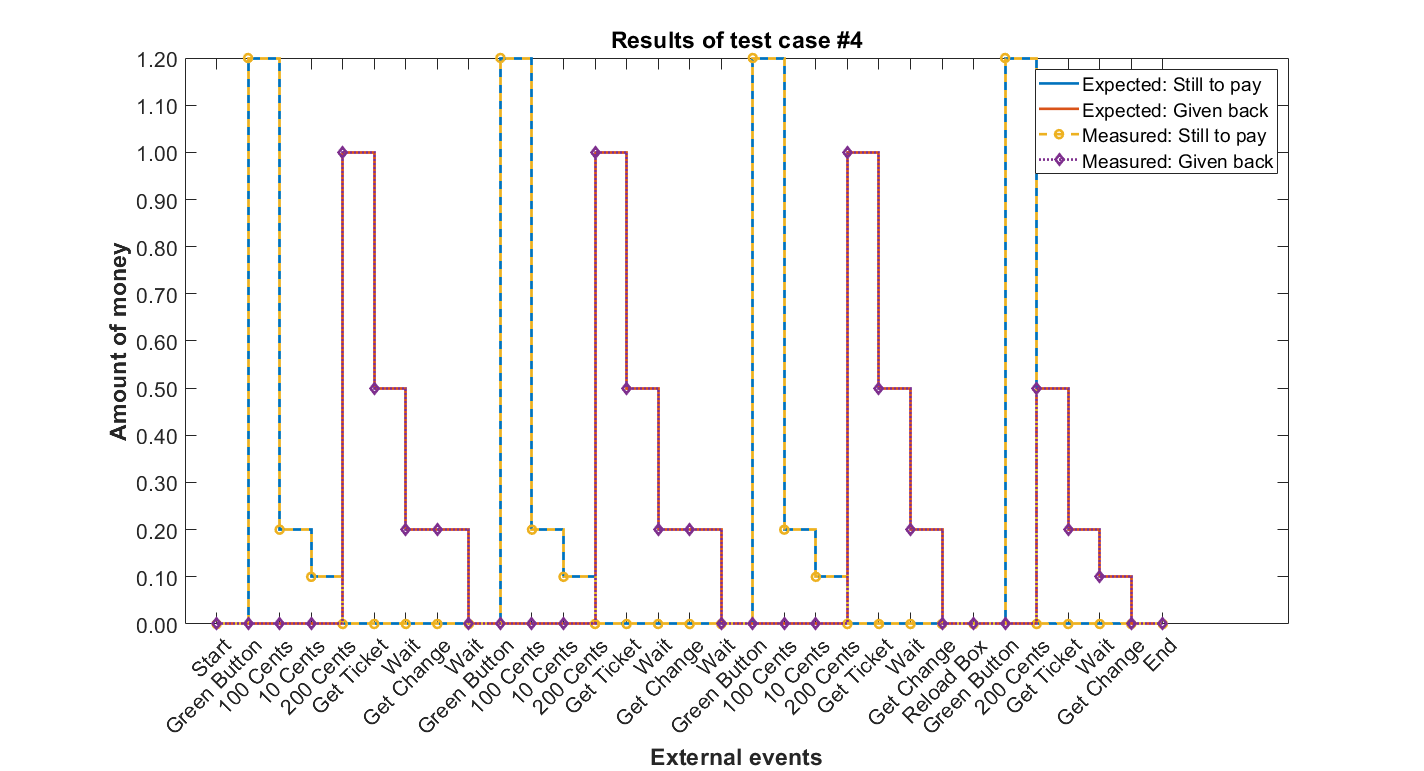


[Terse] Diagnostic logged (2021-02-04 20:27:23):
Figure saved to:
--> C:\Users\sebas\AppData\Local\Temp\f01bf09c-8367-49fb-94e4-bc85156d4bf1\Figure_d8ad6452-6c81-44fb-bdf0-d40ec9983f97.fig
--> C:\Users\sebas\AppData\Local\Temp\f01bf09c-8367-49fb-94e4-bc85156d4bf1\Figure_d8ad6452-6c81-44fb-bdf0-d40ec9983f97.png
.
Done TestApp
__________

Generating test report. Please wait.
    Preparing content for the test report.


    Adding content to the test report.
    Writing test report to file.
Test report has been saved to:
 D:\GitHub\C_Code_Integration\MATLAB\Work\Report.docx
Code coverage report has been saved to:
 C:\Users\sebas\AppData\Local\Temp\tpb250c0a9_7091_4286_9fd9_1cf07c5ee2a5\index.html


% Call the unit testing framework for automated testing
results = runner.run(classSuite);

% Close the running instance of the low-level application
system('taskkill /F /im ParkingMeterProject.exe /im cmd.exe &');

## 5. Results Summary

disp(results.table);

                            Name                            Passed    Failed    Incomplete    Duration      Details   
    ____________________________________________________    ______    ______    __________    ________    ____________

    {'TestApp/testCase_1_StraightTicketPurchase'       }    true      false       false        26.464     {1×1 struct}
    {'TestApp/testCase_2_CancelTicketPurchase'         }    true      false       false        23.092     {1×1 struct}
    {'TestApp/testCase_3_BiggestChangeOnTicketPurchase'}    true      false       false        30.413     {1×1 struct}
    {'TestApp/testCase_4_FullyEmptyAndReloadCashBox'   }    true      false       false        90.798     {1×1 struct}

